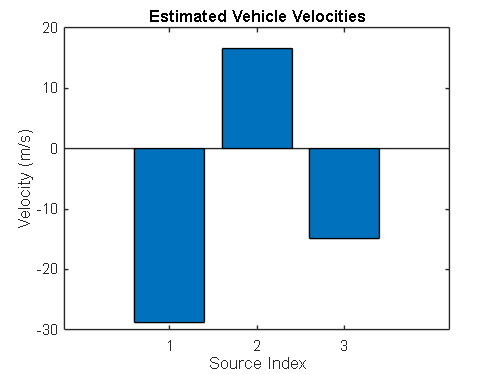

% AOA_MUSIC_V2X_STEP6.m - Complete MUSIC-based V2X AoA Estimation with Kalman Tracking

% Simulation parameters
M = 8;                      % Number of antennas
K = 3;                      % Number of sources (vehicles)
d = 0.0107 / 2;             % Antenna spacing (half-wavelength)
wavelength = 0.0107;        % Wavelength at 28 GHz
SNR = 20;                   % Default SNR for beamforming
fs = 1e6;                   % Sampling frequency
N = 1024;                   % Number of snapshots

% Generate V2X signal
[x, ~, true_DoAs, doppler_shifts, speeds] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs);

% Step 1: Estimate DoAs
doa_estimates = algo(x, M, K, d, wavelength);

% Step 2: Estimate velocities from Doppler
estimated_velocities = estimate_velocity(doa_estimates, doppler_shifts, wavelength);

True DoAs (deg):
  -11.6899   17.3924   30.2877

Estimated DoAs (deg):
   17.4000  -11.7000   30.3000

Doppler shifts (Hz):
   1.0e+03 *

   -2.6875    1.5510   -1.3855

Estimated Velocities (m/s):
  -28.7943   16.6174  -14.8444



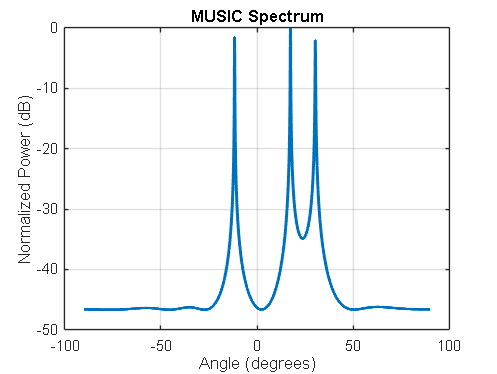

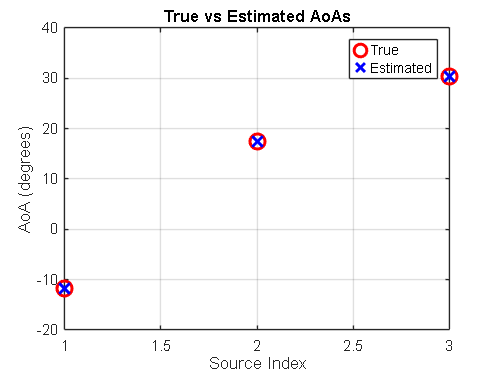


% Step 3: Apply Beamforming (Delay-and-Sum)
x_beamformed = beamform(x, doa_estimates, M, d, wavelength);

% Step 4: Plot Results
plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, estimated_velocities);

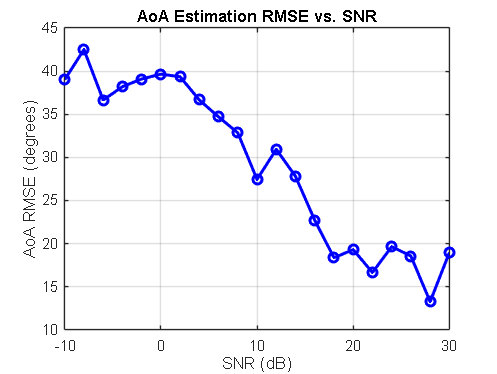


% Step 5: SNR Performance Analysis
SNR_dB_range = -10:2:30;
num_trials = 100;
rmse_results = zeros(size(SNR_dB_range));

for idx = 1:length(SNR_dB_range)
    snr_db = SNR_dB_range(idx);
    doa_errors = zeros(num_trials, K);

    for trial = 1:num_trials
        [x, ~, true_DoAs, ~, ~] = v2x_signal_simulation(M, K, d, wavelength, snr_db, N, fs);
        doa_est = algo(x, M, K, d, wavelength);
        doa_errors(trial, :) = sort(doa_est) - sort(true_DoAs);
    end

    mse = mean(doa_errors(:).^2);
    rmse_results(idx) = sqrt(mse);
end

figure;
plot(SNR_dB_range, rmse_results, 'bo-', 'LineWidth', 2);
xlabel('SNR (dB)'); ylabel('AoA RMSE (degrees)');
title('AoA Estimation RMSE vs. SNR');
grid on;

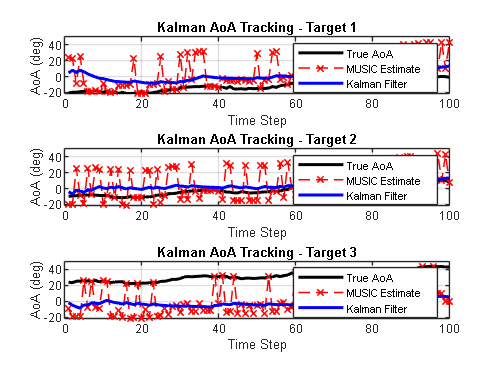


% Step 6: Kalman Filter Tracking for DoA
num_time_steps = 100;
doa_trajectory = zeros(num_time_steps, K);
doa_measured = zeros(num_time_steps, K);
doa_filtered = zeros(num_time_steps, K);

Q = 0.01;   % Process noise variance
R = 4;      % Measurement noise variance
x_hat = zeros(1, K);    % Estimated state (DoA)
P = ones(1, K);         % Error covariance

for t = 1:num_time_steps
    doa_trajectory(t,:) = true_DoAs + 0.2*t + 3*sin(2*pi*t/30 + rand(1,K));
    theta = deg2rad(doa_trajectory(t,:));
    A_t = exp(-1i*2*pi*d*(0:M-1).' * sin(theta)/wavelength);

    S_t = sqrt(0.5)*(randn(K,N) + 1i*randn(K,N));
    noise_var = 10^(-SNR/10) * trace(A_t*(S_t*S_t')*A_t') / (M*N);
    noise = sqrt(noise_var/2) * (randn(M,N) + 1i*randn(M,N));
    x_t = A_t * S_t + noise;

    doa_est_t = algo(x_t, M, K, d, wavelength);
    doa_measured(t,:) = doa_est_t;

    for k = 1:K
        x_pred = x_hat(k);
        P_pred = P(k) + Q;
        K_gain = P_pred / (P_pred + R);
        x_hat(k) = x_pred + K_gain * (doa_measured(t,k) - x_pred);
        P(k) = (1 - K_gain) * P_pred;
        doa_filtered(t,k) = x_hat(k);
    end
end

figure;
for k = 1:K
    subplot(K,1,k);
    plot(1:num_time_steps, doa_trajectory(:,k), 'k-', 'LineWidth', 2); hold on;
    plot(1:num_time_steps, doa_measured(:,k), 'rx--', 'LineWidth', 1);
    plot(1:num_time_steps, doa_filtered(:,k), 'b-', 'LineWidth', 2);
    xlabel('Time Step'); ylabel('AoA (deg)');
    title(['Kalman AoA Tracking - Target ', num2str(k)]);
    legend('True AoA', 'MUSIC Estimate', 'Kalman Filter');
    grid on;
end


%% FUNCTION DEFINITIONS
function [x, A, true_DoAs, doppler_shifts, speeds] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs)
    c = 3e8;
    fc = 28e9;
    t = (0:N-1)/fs;
    true_DoAs = sort(-60 + 120 * rand(1, K));
    speeds = -30 + 60 * rand(1, K);
    doppler_shifts = fc * speeds / c;
    theta = deg2rad(true_DoAs);
    A = exp(-1i*2*pi*d*(0:M-1).' * sin(theta)/wavelength);
    S = zeros(K, N);
    for k = 1:K
        S(k,:) = sqrt(0.5)*(randn(1,N) + 1i*randn(1,N)) .* exp(1i*2*pi*doppler_shifts(k)*t);
    end
    noise_var = 10^(-SNR/10) * trace(A*(S*S')*A') / (M*N);
    noise = sqrt(noise_var/2) * (randn(M,N) + 1i*randn(M,N));
    x = A * S + noise;
end

function doa_estimates = algo(x, M, K, d, wavelength)
    theta = -90:0.1:90;
    [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);
    [~, idx] = sort(Pmusic, 'descend');
    idx = idx(1:K);
    initial_DoAs = theta(idx);
    doa_estimates = zeros(1, K);
    for i = 1:K
        err = @(xval) abs(1 / abs((a(xval,d,M,wavelength)' * Vn)*(Vn' * a(xval,d,M,wavelength))) - Pmusic(idx(i)));
        doa_estimates(i) = fminsearch(err, initial_DoAs(i));
    end
end

function a_vec = a(angle, d, M, wavelength)
    a_vec = exp(-1i * 2*pi * d * (0:M-1).' * sind(angle) / wavelength);
end

function [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta)
    Rxx = (x*x') / size(x,2);
    [V,D] = eig(Rxx);
    [~,idx] = sort(diag(D), 'descend');
    V = V(:,idx);
    Vn = V(:, K+1:end);
    Pmusic = arrayfun(@(ang) 1 / abs((a(ang,d,M,wavelength)' * Vn)*(Vn' * a(ang,d,M,wavelength))), theta);
end

function estimated_velocities = estimate_velocity(doa_estimates, doppler_shifts, wavelength)
    c = 3e8;
    fc = 28e9;
    estimated_velocities = (doppler_shifts * c) / fc;
    figure;
    bar(1:length(estimated_velocities), estimated_velocities);
    xlabel('Source Index'); ylabel('Velocity (m/s)');
    title('Estimated Vehicle Velocities');
end

function x_bf = beamform(x, doa_estimates, M, d, wavelength)
    N = size(x, 2);
    x_bf = zeros(1, N);
    for k = 1:length(doa_estimates)
        w = a(doa_estimates(k), d, M, wavelength);
        w = w / norm(w);
        x_bf = x_bf + (w' * x);
    end
    x_bf = x_bf / length(doa_estimates);
end

function plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, est_vel)
    theta = -90:0.1:90;
    [~, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);
    disp('True DoAs (deg):'); disp(true_DoAs);
    disp('Estimated DoAs (deg):'); disp(doa_estimates);
    disp('Doppler shifts (Hz):'); disp(doppler_shifts);
    disp('Estimated Velocities (m/s):'); disp(est_vel);
    figure;
    plot(theta, 10*log10(abs(Pmusic)/max(abs(Pmusic))), 'LineWidth', 2);
    xlabel('Angle (degrees)'); ylabel('Normalized Power (dB)');
    title('MUSIC Spectrum'); grid on;
    figure;
    plot(1:K, sort(true_DoAs), 'ro', 'LineWidth', 2, 'MarkerSize', 10); hold on;
    plot(1:K, sort(doa_estimates), 'bx', 'LineWidth', 2, 'MarkerSize', 10);
    xlabel('Source Index'); ylabel('AoA (degrees)');
    title('True vs Estimated AoAs'); legend('True', 'Estimated');
    grid on;
end
